# Data Driven Simulation Nuclear Norm

## First attempt future prediction with 3 states

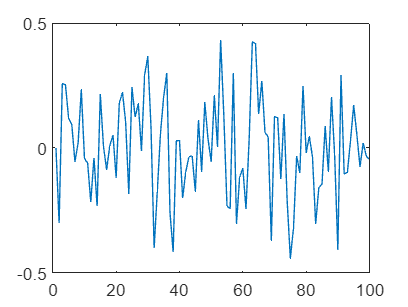

addpath('./tensorlab');
addpath('./cvx');

% Define system dimensions
statenum = 3;
outputnum = 1;
inputnum = 1;
maxTime = 100; % Total time for simulation of historical data
predTime = 1; % Part of the time that is the future

% Create a discrete-time random state space model
sys = drss(statenum, outputnum, inputnum);

% Generate a persistently exciting input for historical data
% For example, a random signal
u_trajectory = randn(inputnum, maxTime)';

% New input for prediction
% newInputTime = predTime; % Length of new input
% uf = randn(inputnum, newInputTime); % New input sequence
% uf = zeros(inputnum,1); %zero input

% Simulate the system to generate historical outputs
% Assuming zero initial state for simplicity
x0 = zeros(statenum, 1); % Initial state
[data, t, x] = lsim(sys, u_trajectory, linspace(0, maxTime-1, maxTime), x0);
plot(data)

% scaling the past data by some gamma

minValue = min(min(data(:)),min(u_trajectory(:)));
maxValue = max(max(data(:)),max(u_trajectory(:)));

absoluteLargestValue = max(abs(minValue),abs(maxValue));

gamma = 10^ceil(log10(absoluteLargestValue))

gamma =     10



% normalize everything except future points
dataNorm = data/gamma

dataNorm =                    0
  -0.030001324160856
   0.025755958555684
   0.025248863490320
   0.011903565154628
   0.009397001620395
  -0.005546135769671
   0.002019800111470
   0.023482452502426
  -0.004200708140953


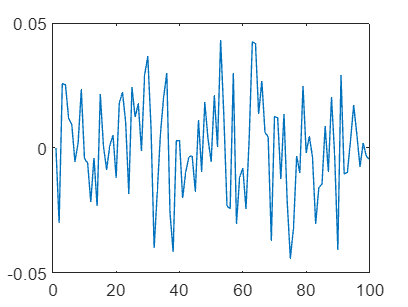

u_trajectoryNorm = u_trajectory/gamma;

plot(dataNorm)


dataLength = length(data);

lag = 11;

% Create the full Hankel matrix without missing values initially
HankelMatrix = mosaicHankel(u_trajectoryNorm, dataNorm, lag);

OriginalHankel = HankelMatrix;

% Define the number of points we want to predict (missing at the end)
numPredict = 1;

% Create a logical mask for the Hankel matrix with all ones (no missing data)
mask = true(size(HankelMatrix));

% Identify the columns in the Hankel matrix that correspond to the last 'numPredict' points
% These points appea5r in the last 'numPredict' rows of the last columns

% For the last column
mask(end-numPredict+1:end, end) = false;

%{
for i = 1:numPredict
    mask(end-i+1, end-numPredict+i:end) = false;
end
%}

% Now, apply the mask to set the last 'numPredict' points as NaN (missing)
HankelMatrix(~mask) = NaN;

% Proceed with matrix completion using the nuclear norm minimization (using CVX)
cvx_begin quiet %sdp for logs
    variable CompleteHankel(size(HankelMatrix))
    minimize(norm_nuc(CompleteHankel))
    subject to
        % Ensure the known entries remain the same
        CompleteHankel(mask) == HankelMatrix(mask);
cvx_end
% Check the completion status
disp(cvx_status);

Solved



predictedValues = CompleteHankel(end, end-numPredict+1:end)*gamma;

disp('Predicted value:');

Predicted value:


format long;
disp(predictedValues);

  -0.045063830438289



disp('Actual value:');

Actual value:


disp(transpose(data(end-numPredict+1:end)))

  -0.045063830657475



%rmse(predictedValues,transpose(data(end-numPredict+1:end)))
%currentError = abs(predictedValues-transpose(data(end-numPredict+1:end)))/abs(predictedValues)

currentError = norm(predictedValues,2)/norm(transpose(data(end-numPredict+1:end)))

currentError =    0.999999995136098


## Multiple iterations with 10 states

% Number of iterations
iterations = 20;

% Initialize arrays to store results
predictedValues = zeros(iterations, 1);
actualValues = zeros(iterations, 1);
errors = zeros(iterations, 1);

for iter = 1:iterations
   % Define system dimensions
    statenum = 10;
    outputnum = 1;
    inputnum = 1;
    maxTime = 100; % Total time for simulation of historical data
    predTime = 1; % Part of the time that is the future
    
    % Create a discrete-time random state space model
    sys = drss(statenum, outputnum, inputnum);
    
    % Generate a persistently exciting input for historical data
    % For example, a random signal
    u_trajectory = randn(inputnum, maxTime)';
    
    % New input for prediction
    % newInputTime = predTime; % Length of new input
    % uf = randn(inputnum, newInputTime); % New input sequence
    % uf = zeros(inputnum,1); %zero input
    
    % Simulate the system to generate historical outputs
    % Assuming zero initial state for simplicity
    x0 = zeros(statenum, 1); % Initial state
    [data, t, x] = lsim(sys, u_trajectory, linspace(0, maxTime-1, maxTime), x0);
    % scaling the past data by some gamma
    
    minValue = min(min(data(:)),min(u_trajectory(:)));
    maxValue = max(max(data(:)),max(u_trajectory(:)));
    
    absoluteLargestValue = max(abs(minValue),abs(maxValue));
    
    gamma = 10^ceil(log10(absoluteLargestValue));
    
    % normalize everything except future points
    dataNorm = data/gamma;
    u_trajectoryNorm = u_trajectory/gamma;
    
    
    dataLength = length(data);
    
    lag = statenum+1;
    
    % Create the full Hankel matrix without missing values initially
    HankelMatrix = mosaicHankel(u_trajectoryNorm, dataNorm, lag);
    
    % Define the number of points we want to predict (missing at the end)
    numPredict = 1;
    
    % Create a logical mask for the Hankel matrix with all ones (no missing data)
    mask = true(size(HankelMatrix));
    
    % Identify the columns in the Hankel matrix that correspond to the last 'numPredict' points
    % These points appea5r in the last 'numPredict' rows of the last columns
    
    % For the last column
    mask(end-numPredict+1:end, end) = false;
    
    %{
    for i = 1:numPredict
        mask(end-i+1, end-numPredict+i:end) = false;
    end
    %}
    
    % Now, apply the mask to set the last 'numPredict' points as NaN (missing)
    HankelMatrix(~mask) = NaN;
    
    % Proceed with matrix completion using the nuclear norm minimization (using CVX)
    cvx_begin quiet %sdp for logs
        variable CompleteHankel(size(HankelMatrix))
        minimize(norm_nuc(CompleteHankel))
        subject to
            % Ensure the known entries remain the same
            CompleteHankel(mask) == HankelMatrix(mask);
    cvx_end


    predicted = CompleteHankel(end, end-numPredict+1:end)*gamma;

    %rmse(predictedValues,transpose(data(end-numPredict+1:end)))
    %currentError = abs(predictedValues-transpose(data(end-numPredict+1:end)))/abs(predictedValues)
    
    currentError = norm(predicted,2)/norm(transpose(data(end-numPredict+1:end)));

    % Denormalize the predicted values
    predictedValues(iter) = predicted;
    actualValues(iter) = data(end - numPredict + 1:end);

    % Calculate the relative error
    errors(iter) = currentError;

    % Display the status for debugging
    disp(['Iteration ', num2str(iter), ':']);
    disp(['Predicted value: ', num2str(predictedValues(iter))]);
    disp(['Actual value: ', num2str(actualValues(iter))]);
    disp(['Relative error: ', num2str(errors(iter))]);
end

Iteration 1:


Predicted value: 34.9664


Actual value: 34.9664


Relative error: 1


Iteration 2:


Predicted value: -8.4238


Actual value: -8.4238


Relative error: 1


Iteration 3:


Predicted value: -4.7227


Actual value: -4.7227


Relative error: 1


Iteration 4:


Predicted value: 1.9166


Actual value: 1.9166


Relative error: 1


Iteration 5:


Predicted value: 3.195


Actual value: 3.195


Relative error: 1


Iteration 6:


Predicted value: -2.177


Actual value: -2.177


Relative error: 1


Iteration 7:


Predicted value: 4.2247


Actual value: 4.2247


Relative error: 1


Iteration 8:


Predicted value: -0.29453


Actual value: -0.29453


Relative error: 1


Iteration 9:


Predicted value: 0.30436


Actual value: 0.30436


Relative error: 1


Iteration 10:


Predicted value: -14.6605


Actual value: -14.6605


Relative error: 1


Iteration 11:


Predicted value: -2.0953


Actual value: -2.0953


Relative error: 1


Iteration 12:


Predicted value: 35.3598


Actual value: 35.3595


Relative error: 1


Iteration 13:


Predicted value: 22.3234


Actual value: 22.3234


Relative error: 1


Iteration 14:


Predicted value: -0.59648


Actual value: -0.59648


Relative error: 1


Iteration 15:


Predicted value: 2.7158


Actual value: 2.7158


Relative error: 1


Iteration 16:


Predicted value: -1.806


Actual value: -1.806


Relative error: 1


Iteration 17:


Predicted value: -6.3956


Actual value: -7.4887


Relative error: 0.85403


Iteration 18:


Predicted value: 3.4363


Actual value: 3.4363


Relative error: 1


Iteration 19:


Predicted value: 1.0057


Actual value: 1.0057


Relative error: 1


Iteration 20:


Predicted value: 3.2046


Actual value: 3.2046


Relative error: 1



% Calculate the average relative error
avgError = mean(errors);
rmseError = sqrt(mean((predictedValues - actualValues).^2));

disp("Average relative error: " + avgError);

Average relative error: 0.9927


disp("RMSE: " + rmseError);

RMSE: 0.24442


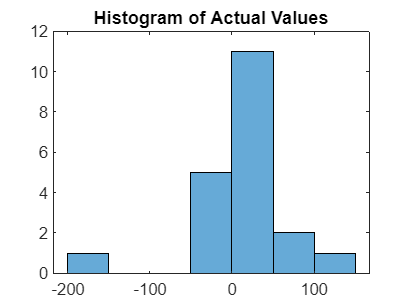


figure;
histogram(errors);
title('Histogram of Errors');

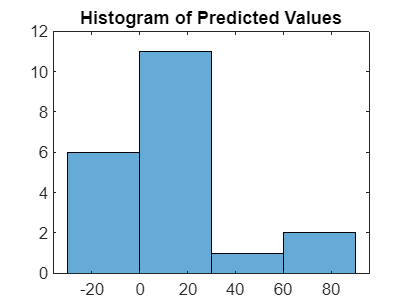


figure;
histogram(predictedValues);
title('Histogram of Predicted Values');

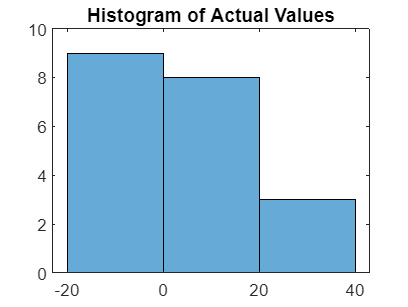

Average relative error: 0.45536


RMSE: 0.25923


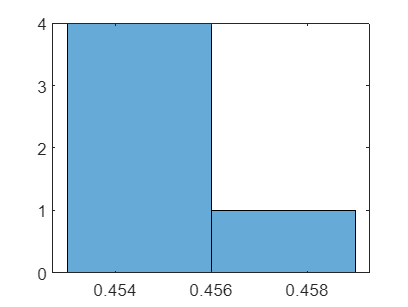

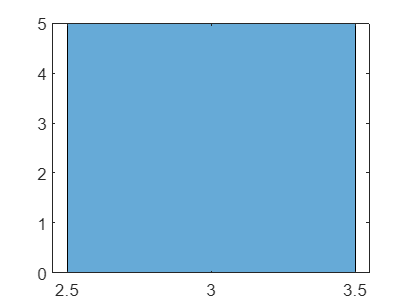

Average relative error: 90.8176


RMSE: 8.5821


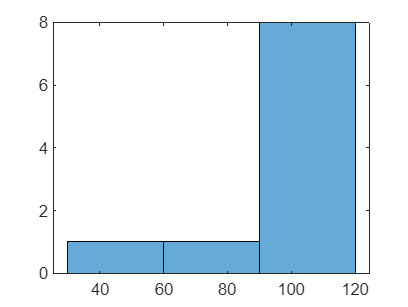

Average relative error: 0.091064


RMSE: 20.9794


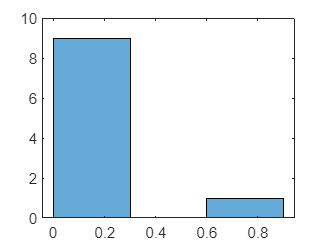

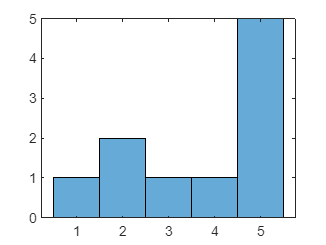


figure;
histogram(actualValues);
title('Histogram of Actual Values');